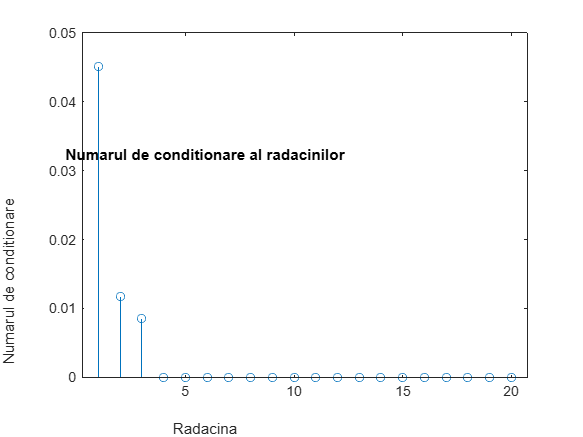

%polinomul (x - 1)(x - 2)...(x - n)
n = 20;
p = poly(1:n);

%radacinile
roots_exact = roots(p);

%calcul nr. de conditionare pt fiecare radacina
cond_numbers = zeros(n, 1);

%ca sa fie aleatoare normala dispersia
%ca sa fie uniforma:  unifrnd(1, n+1) * 1e-10
perturbation = normrnd(0,1e-10);

for i = 1:n
    p_perturbed = p;
    
    %de fiecare data perturb un coeficient
    p_perturbed(i) = p_perturbed(i) + perturbation;
    
    %aflam iar radacinile si conditionarea 
    %aka cat de mult o influentat perturbarea noastra rez final
    roots_perturbed = roots(p_perturbed);
    cond_numbers(i) = norm(roots_perturbed - roots_exact)/norm(roots_exact);
end

%graficul nr. de conditionare al fiecarei radacini
figure;
stem(1:n, cond_numbers);
title('Numarul de conditionare al radacinilor');
xlabel('Radacina');
ylabel('Numarul de conditionare');


%perturbarea cu variabile aleatoare normale
%init o perturbare care urmeaza distributie normala
perturbation_normal = normrnd(0,1e-10);
p_perturbed_normal = p + perturbation_normal;
roots_perturbed_normal = roots(p_perturbed_normal);
error_perturbed_normal = norm(roots_perturbed_normal-roots_exact)/norm(roots_exact);
fprintf('error with normal perturbation %f\n',error_perturbed_normal);

error with normal perturbation 0.031889



%perturbarea cu variabile aleatoare uniforme
%init o perturbare care urmeaza distributie uniforma
perturbation_uniform = unifrnd(1, n+1) * 1e-10;
p_perturbed_uniform = p + perturbation_uniform;
roots_perturbed_uniform = roots(p_perturbed_uniform);
error_perturbed_uniform = norm(roots_perturbed_uniform-roots_exact)/norm(roots_exact);
fprintf('error with uniform perturbation %f\n',error_perturbed_uniform);

error with uniform perturbation 0.067233


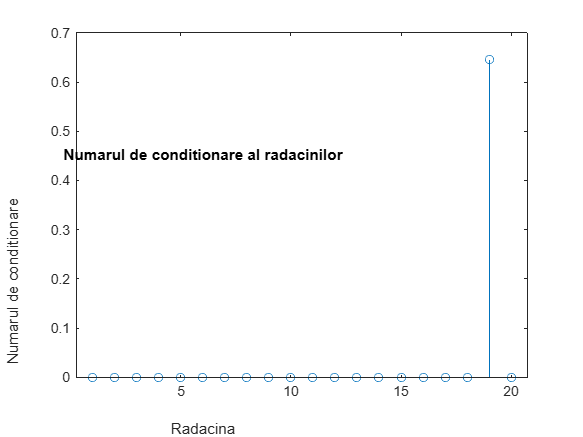

% polinomul x^n+x^(n-1) /2  +x^(n-2) /2^2 + ....
n = 20;
p = 2.^-(1:n); 

%radacinile
roots_exact = roots(p);

%calcul nr. de conditionare pt fiecare radacina
cond_numbers = zeros(n, 1);

%ca sa fie aleatoare dispersia
%ca sa fie uniforma:  unifrnd(1, n+1) * 1e-10
perturbation = normrnd(0,1e-10);

for i = 1:n
    p_perturbed = p;
    
    %de fiecare data perturb un coeficient
    p_perturbed(i) = p_perturbed(i) + perturbation;
    
    %aflam iar radacinile si conditionarea 
    %aka cat de mult o influentat perturbarea noastra rez final
    roots_perturbed = roots(p_perturbed);
    cond_numbers(i) = norm(roots_perturbed - roots_exact)/norm(roots_exact);
end

%graficul nr. de conditionare al fiecarei radacini
figure;
stem(1:n, cond_numbers);
title('Numarul de conditionare al radacinilor');
xlabel('Radacina');
ylabel('Numarul de conditionare');


%perturbarea cu variabile aleatoare normale
%init o perturbare care urmeaza distributie normala
perturbation_normal = normrnd(0,1) * 1e-10;
p_perturbed_normal = p + perturbation_normal;
roots_perturbed_normal = roots(p_perturbed_normal);
error_perturbed_normal = norm(roots_perturbed_normal-roots_exact)/norm(roots_exact);
fprintf('error with normal perturbation %f\n',error_perturbed_normal);

error with normal perturbation 0.555900



%perturbarea cu variabile aleatoare uniforme
%init o perturbare care urmeaza distributie uniforma
perturbation_uniform = unifrnd(1, n+1) * 1e-10;
p_perturbed_uniform = p + perturbation_uniform;
roots_perturbed_uniform = roots(p_perturbed_uniform);
error_perturbed_uniform = norm(roots_perturbed_uniform-roots_exact)/norm(roots_exact);
fprintf('error with uniform perturbation %f\n',error_perturbed_uniform);

error with uniform perturbation 0.537986
